1. Загрузите данные **ex3data1.mat **из файла.

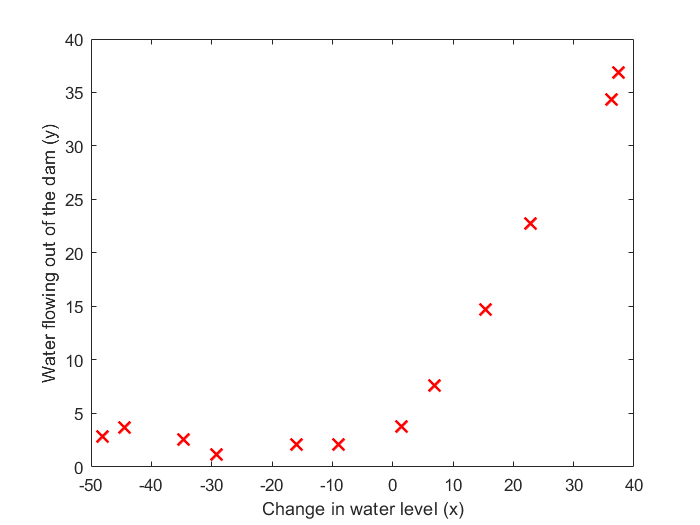

load ('ex5data1.mat');

2. Постройте график, где по осям откладываются X и y из обучающей выборки.

figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

3. Реализуйте функцию стоимости потерь для линейной регрессии с L2-регуляризацией.

4. Реализуйте функцию градиентного спуска для линейной регрессии с L2-регуляризацией.

5. Постройте модель линейной регрессии с коэффициентом регуляризации 0 и постройте график полученной функции совместно с графиком из пункта 2. Почему регуляризация в данном случае не сработает?

lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     4 | Cost: 2.237391e+01
Iteration     5 | Cost: 2.237391e+01
Iteration     6 | Cost: 2.237391e+01


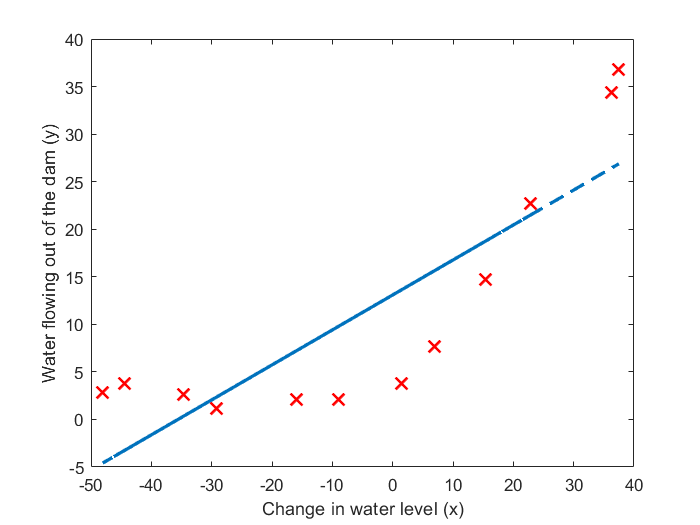

figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

Регуляризация не сработает потому что слишком маленькая размерность тета.

6. Постройте график процесса обучения (learning curves) для обучающей и валидационной выборки. По оси абсцисс откладывается число элементов из обучающей выборки, а по оси ординат - ошибка (значение функции потерь) для обучающей выборки (первая кривая) и валидационной выборки (вторая кривая). Какой вывод можно сделать по построенному графику?

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.843147e+00
Iteration     7 | Cost: 2.842791e+00
Iteration     8 | Cost: 2.842765e+00
Iteration     9 | Cost: 2.842679e+00
Iteration    10 | Cost: 2.842679e+00
Iteration    11 | Cost: 2.842679e+00
Iteration    12 | Cost: 2.842678e+00
Iteration    13 | Cost: 2.842678e+00
Iteration    14 | Cost: 2.842678e+00
Iteration    15 | Cost: 2.842678e+00
Iteration    16 | Cost: 2.842678e+00
Iteration    17 | Cost: 2.842678e+00
Iteration    18 | Cost: 2.842678e+00
Iteration    19 | Cost: 2.842678e+00
I

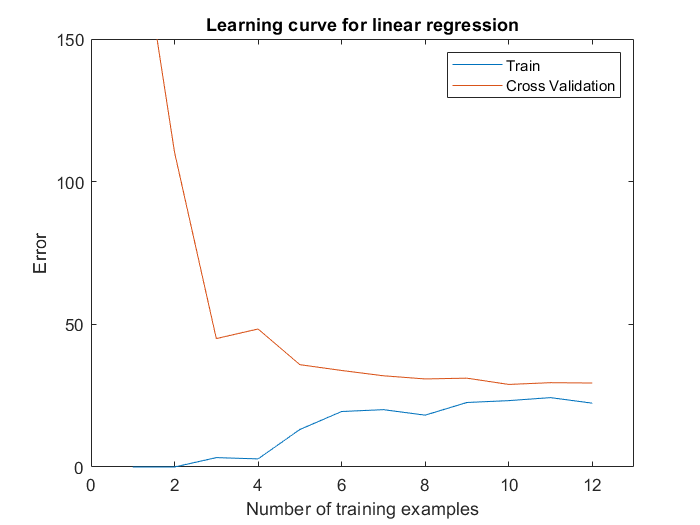


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


Ошибка на тестовом и валидационном сете высокая. Модель слишком простая чтобы подстроиться под данные.

7. Реализуйте функцию добавления p - 1 новых признаков в обучающую выборку (X2, X3, X4, …, Xp).

8. Поскольку в данной задаче будет использован полином высокой степени, то необходимо перед обучением произвести нормализацию признаков.

9. Обучите модель с коэффициентом регуляризации 0 и p = 8.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411245e-01
Iteration    11 | Cost: 7.802115e-01
Iteration    12 | Cost: 7.270456e-01
Iteration    13 | Cost: 6.577683e-01
Iteration    14 | Cost: 5.106861e-01
Iteration    15 | Cost: 4.734015e-01
Iteration    16 | Cost: 4.222337e-01
Iteration    17 | Cost: 4.209566e-01
Iteration    18 | Cost: 4.179436e-01
Iteration    19 | Cost: 4.149038e-01
Iteration    20 | Cost: 4.048243e-01
Iteration    21 | Cost: 4.003634e-01
Iteration    22 | Cost: 3.952067e-01
Iteration    23 | Cost: 3.842805e-01
Iteration    24 | Cost: 3.514872e-01
Iteration    25 | Cost: 3.485057e-01
Iteration    26 | Cost: 3.440929e-01
Iteration    27 | Cost: 3.433698e-01
I

10. Постройте график модели, совмещенный с обучающей выборкой, а также график процесса обучения. Какой вывод можно сделать в данном случае?

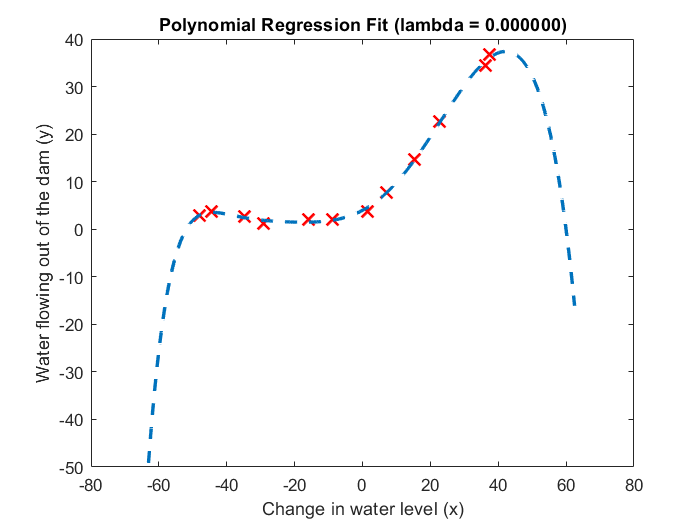

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 0.000000e+00
Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 1.880576e-10
Iteration     5 | Cost: 1.880553e-10
Iteration     6 | Cost: 9.442954e-11
Iteration     7 | Cost: 6.841388e-15
Iteration     8 | Cost: 6.840914e-15
Iteration     9 | Cost: 3.450009e-15
Iteration    10 | Cost: 1.012558e-18
Iteration    11 | Cost: 1.012253e-18
Iteration    12 | Cost: 4.823455e-19
Iteration    13 | Cost: 4.688636e-21
Iteration    14 | Cost: 2.246403e-21
Iteration    15 | Cost: 1.707239e-23
Iteration    16 | Cost: 8.176013e-24
Iteration    17 | Cost: 6.342162e-26
Iteration    18 | Cost: 3.030749e-26
Iteration    19 | Cost: 2.544693e-28
Iteration    20 | Cost: 1.136453e-28
Iteration    21 | Cost: 6.569732e-30
Iteration    22 | Cost: 3.907327e-30
Iteration    23 | Cost: 2.095412e-31
Iteration    24 | Cost: 1.232595e-32
Iteration    26 | Cost: 0.000000e+00
I

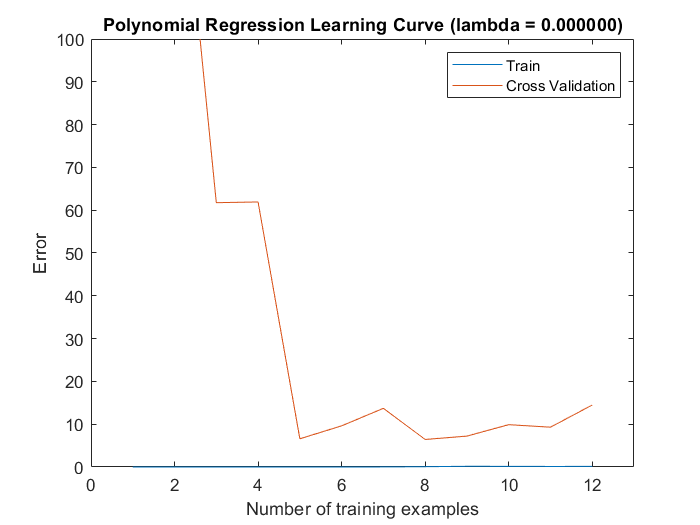

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

   Ошибка на обучающей выборке низкая, но на валидационной высокая. low training error is low, but the cross validation error is high. Проблема high variance.

11. Постройте графики из пункта 10 для моделей с коэффициентами регуляризации 1 и 100. Какие выводы можно сделать?

lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 7.814702e+00
Iteration     5 | Cost: 7.711843e+00
Iteration     6 | Cost: 7.588232e+00
Iteration     7 | Cost: 7.481019e+00
Iteration     8 | Cost: 7.347791e+00
Iteration     9 | Cost: 7.337625e+00
Iteration    10 | Cost: 7.322456e+00
Iteration    11 | Cost: 7.315629e+00
Iteration    12 | Cost: 7.294256e+00
Iteration    13 | Cost: 7.285757e+00
Iteration    14 | Cost: 7.275676e+00
Iteration    15 | Cost: 7.275194e+00
Iteration    16 | Cost: 7.273592e+00
Iteration    17 | Cost: 7.272031e+00
Iteration    18 | Cost: 7.269888e+00
Iteration    19 | Cost: 7.269128e+00
Iteration    20 | Cost: 7.269033e+00
Iteration    21 | Cost: 7.268309e+00
Iteration    22 | Cost: 7.268211e+00
Iteration    23 | Cost: 7.268192e+00
Iteration    24 | Cost: 7.268151e+00
Iteration    25 | Cost: 7.268150e+00
Iteration    26 | Cost: 7.268149e+00
Iteration    27 | Cost: 7.268148e+00
I

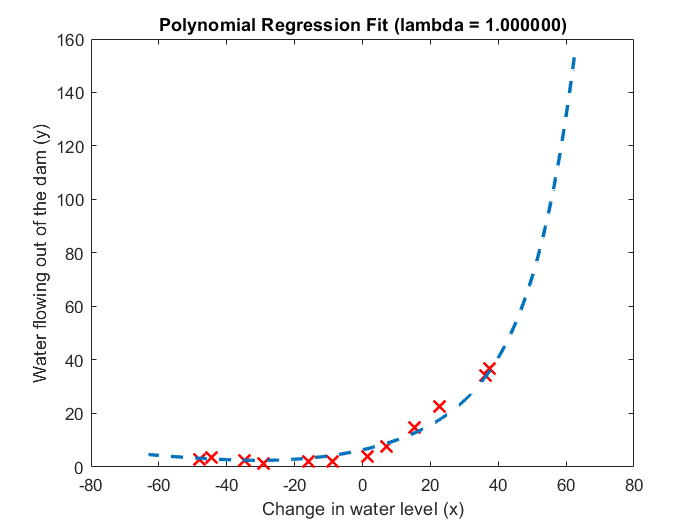

plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 5.280051e-01
Iteration     2 | Cost: 2.083531e-01
Iteration     3 | Cost: 9.810873e-02
Iteration     4 | Cost: 1.501116e-03
Iteration     5 | Cost: 1.089480e-03
Iteration     6 | Cost: 5.204709e-31
Iteration     7 | Cost: 1.745286e-31
Iteration     8 | Cost: 3.643730e-32
Iteration     9 | Cost: 6.001848e-33
Iteration    10 | Cost: 9.121147e-34
Iteration    11 | Cost: 1.855909e-62
Iteration    12 | Cost: 2.113260e-65
Iteration    13 | Cost: 6.814360e-71
Iteration    14 | Cost: 2.197339e-76
Iteration    15 | Cost: 7.085478e-82
Iteration    16 | Cost: 2.284763e-87
Iteration    17 | Cost: 7.367384e-93
Iteration    18 | Cost: 2.375666e-98
Iteration    19 | Cost: 7.660505e-104
Iteration    20 | Cost: 2.470185e-109
Iteration    21 | Cost: 7.965288e-115
Iteration    22 | Cost: 2.568464e-120
Iteration    23 | Cost: 8.282198e-126
Iteration    24 | Cost: 2.670654e-131
Iteration    25 | Cost: 8.611716e-137
Iteration    26 | Cost: 2.776910e-142
Iteration    27 | Cost: 8.9543

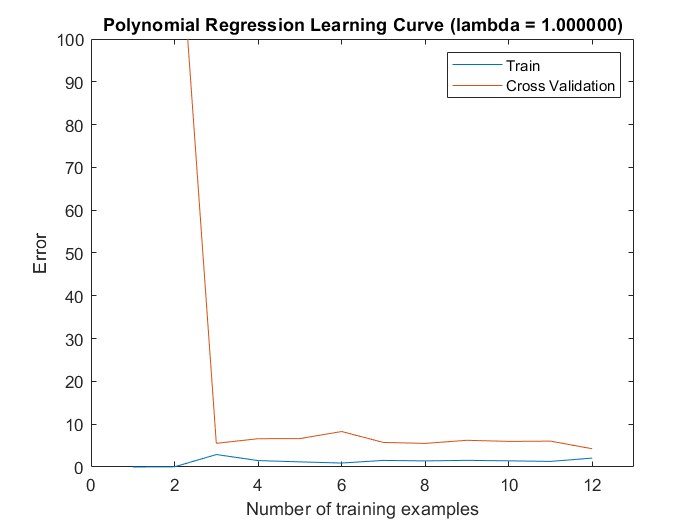

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

lambda = 100;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 1.218518e+02
Iteration     2 | Cost: 8.964311e+01
Iteration     3 | Cost: 7.339016e+01
Iteration     4 | Cost: 7.283318e+01
Iteration     5 | Cost: 6.732411e+01
Iteration     6 | Cost: 6.676558e+01
Iteration     7 | Cost: 6.673472e+01
Iteration     8 | Cost: 6.673391e+01
Iteration     9 | Cost: 6.673354e+01
Iteration    10 | Cost: 6.673329e+01
Iteration    11 | Cost: 6.673322e+01
Iteration    12 | Cost: 6.673317e+01
Iteration    13 | Cost: 6.673317e+01
Iteration    14 | Cost: 6.673316e+01
Iteration    15 | Cost: 6.673316e+01
Iteration    16 | Cost: 6.673316e+01
Iteration    17 | Cost: 6.673316e+01
Iteration    18 | Cost: 6.673316e+01
Iteration    19 | Cost: 6.673316e+01
Iteration    20 | Cost: 6.673316e+01
Iteration    21 | Cost: 6.673316e+01
Iteration    22 | Cost: 6.673316e+01
Iteration    23 | Cost: 6.673316e+01
Iteration    25 | Cost: 6.673316e+01
Iteration    26 | Cost: 6.673316e+01
Iteration    27 | Cost: 6.673316e+01


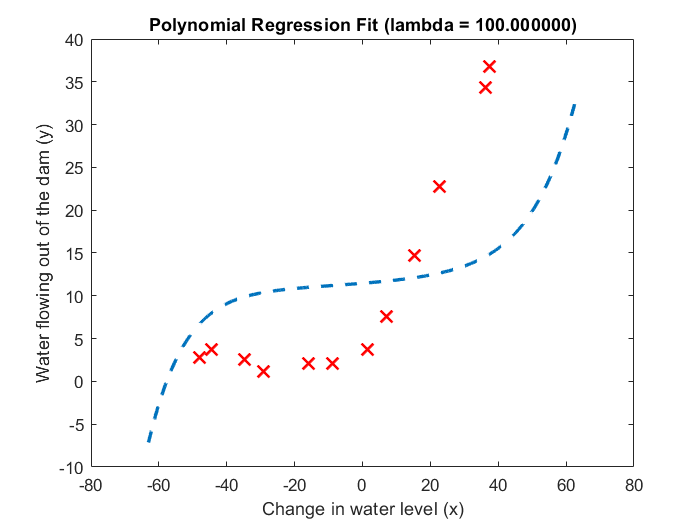

plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 2.178715e+00
Iteration     2 | Cost: 2.980435e-28
Iteration     3 | Cost: 2.828519e-28
Iteration     4 | Cost: 2.440717e-29
Iteration     5 | Cost: 2.313706e-29
Iteration     6 | Cost: 1.219265e-29
Iteration     7 | Cost: 7.885077e-30
Iteration     8 | Cost: 6.076818e-30
Iteration     9 | Cost: 9.145285e-31
Iteration    10 | Cost: 5.814052e-31
Iteration    11 | Cost: 4.149827e-31
Iteration    12 | Cost: 1.805734e-31
Iteration    13 | Cost: 9.904110e-32
Iteration    15 | Cost: 9.862155e-32
Iteration     1 | Cost: 1.377219e+00
Iteration     2 | Cost: 1.913835e-01
Iteration     3 | Cost: 1.909083e-01
Iteration     4 | Cost: 1.574826e-01
Iteration     5 | Cost: 1.167971e-01
Iteration     6 | Cost: 1.167255e-01
Iteration     7 | Cost: 1.160132e-01
Iteration     8 | Cost: 1.151354e-01
Iteration     9 | Cost: 1.149515e-01
Iteration    10 | Cost: 1.148641e-01
Iteration    11 | Cost: 1.147780e-01
Iteration    12 | Cost: 1.147779e-01
Iteration    13 | Cost: 1.147779e-01
I

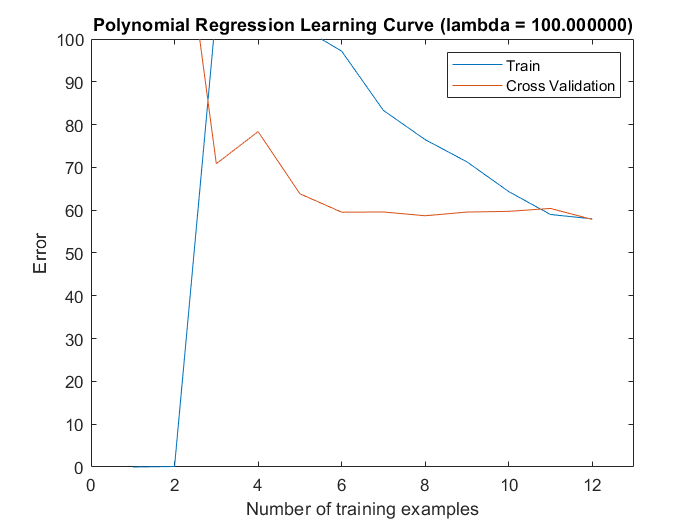

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

Lamda = 1 показал хорошие результаты, Lambda = 100 - слишком большой коэффициент, не подстроилось под данные.

12. С помощью валидационной выборки подберите коэффиент регуляризации, который позволяет достичь наименьшей ошибки. Процесс подбора отразите с помощью графика (графиков).

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411245e-01
Iteration    11 | Cost: 7.802115e-01
Iteration    12 | Cost: 7.270456e-01
Iteration    13 | Cost: 6.577683e-01
Iteration    14 | Cost: 5.106861e-01
Iteration    15 | Cost: 4.734015e-01
Iteration    16 | Cost: 4.222337e-01
Iteration    17 | Cost: 4.209566e-01
Iteration    18 | Cost: 4.179436e-01
Iteration    19 | Cost: 4.149038e-01
Iteration    20 | Cost: 4.048243e-01
Iteration    21 | Cost: 4.003634e-01
Iteration    22 | Cost: 3.952067e-01
Iteration    23 | Cost: 3.842805e-01
Iteration    24 | Cost: 3.514872e-01
Iteration    25 | Cost: 3.485057e-01
Iteration    26 | Cost: 3.440929e-01
Iteration    27 | Cost: 3.433698e-01
I

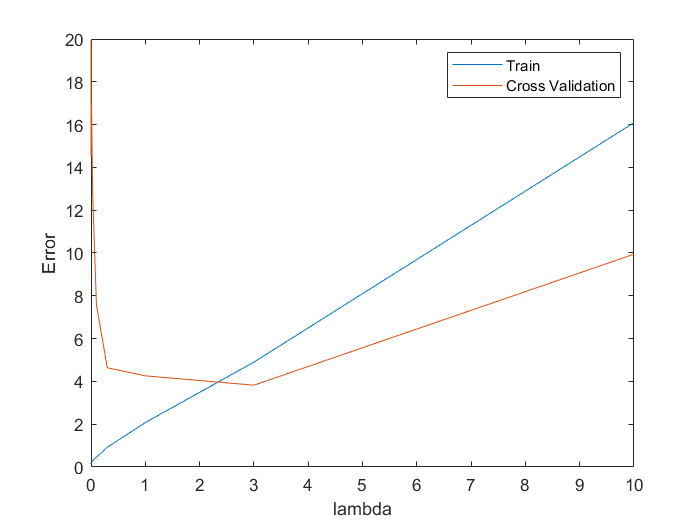

plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.138087	14.486370
0.001000	0.165188	19.929176
0.003000	0.178774	16.813059
0.010000	0.221578	16.986708
0.030000	0.281850	12.828858
0.100000	0.459318	7.587013
0.300000	0.921760	4.636833
1.000000	2.076188	4.260625
3.000000	4.901351	3.822907
10.000000	16.092213	9.945508


Лучший коэффициент  lambda = 3